# Time evolution for a DAE system on a star graph

Evolves the linear Schrodinger equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

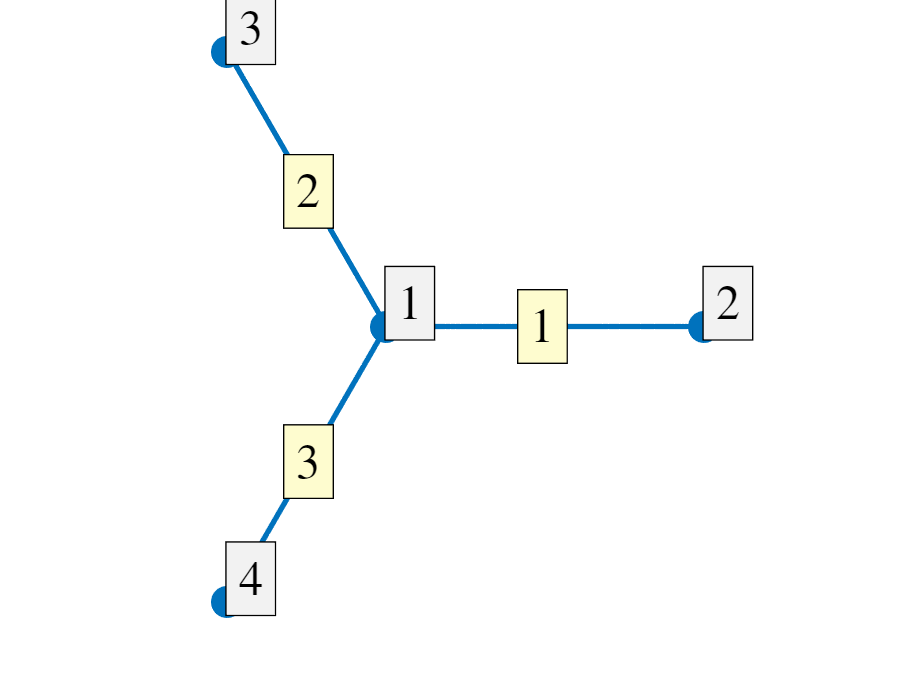

robinCoeff = [0 NaN NaN NaN];
LVec = 8*pi;
nX = 80;
weight = [1 1 1];
Phi = quantumGraphFromTemplate('star','LVec',LVec,'discretization','Chebyshev','nX',nX,'robinCoeff',robinCoeff,'weight',weight);
Phi.plot('layout')

## Define the function

Define the cubic nonlinear Schrodinger time equation on Phi.

A = Phi.laplacianMatrix;
B = Phi.weightMatrix;

f =@(t,z) -1i*( A*z + (2*(B*z).^2.*conj(B*z)));

% fcns= getGraphFcns(Phi);
% Lambda = -1;
% f=@(t,z) fcns.f(z,Lambda);

## Time evolution

The initial condition in this example is a soliton on one of the star's edges that propogates towards the junction.

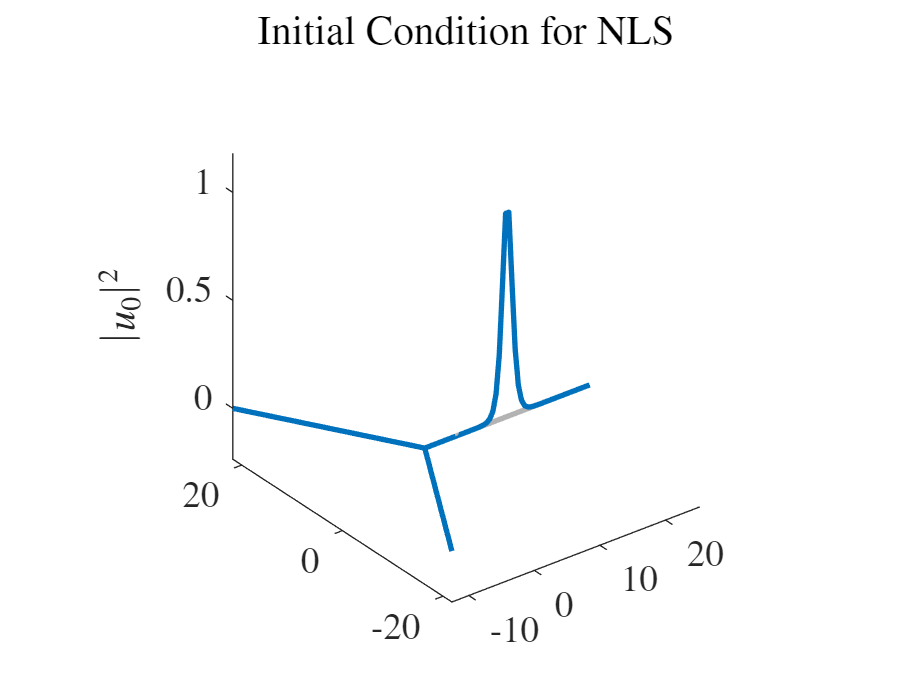

v0 = -4;     % Initial velocity
IC = @(x) exp(1i*-x*v0).*sech(x-LVec/2);    % Solution should be u(x,t)=e^(it)sech(-x+2*pi)
xgrid = LVec*chebptsSecondKind(nX)';
u0 = transpose([IC(xgrid) zeros(1,nX+2) zeros(1,nX+2)]); % Phi.applyFunctionsToAllEdges({@(x) exp(1i*-x*v0).*sech(x-LVec/2),0,0});
Phi.plot(abs(u0).^2)
title('Initial Condition for NLS')
zlabel('$|u_0|^2$')

The only things need for the time evolution are the function being solved, initial condition and end time.

tend = 3.5;
[t,u] = Phi.timeEvolve15s(f,u0,tend);
% [t,u] = Phi.timeEvolveARK(f,u0,10^-05,tend,8);

## Plotting the solution

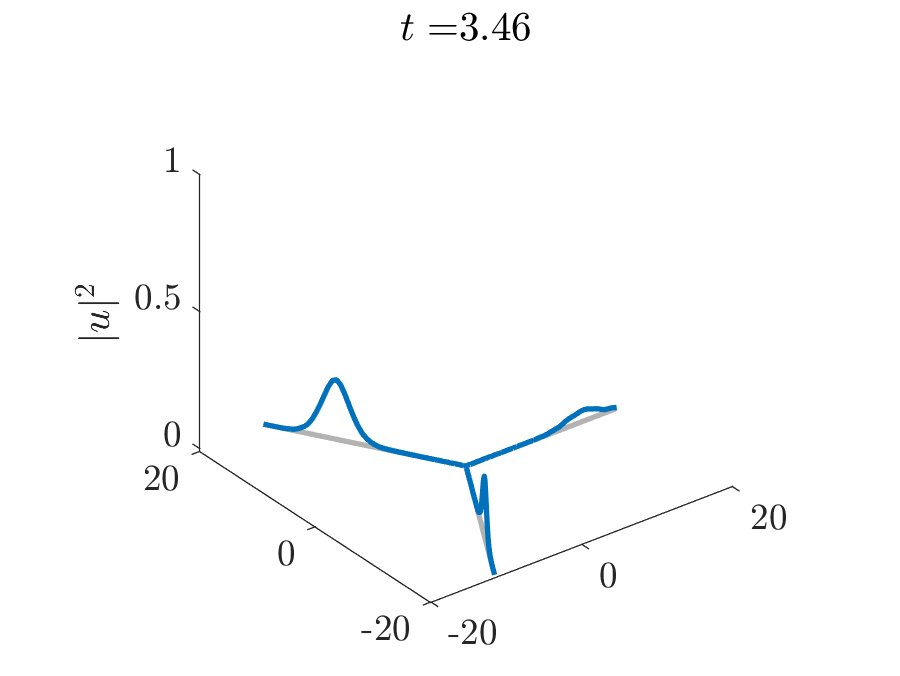

n = size(u,2);
scale = floor(n/100);
for i=1:floor(n/scale)-1
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-20 20 -20 20 -.01 1])
    daspect([1 1 0.03])
    title(['$t=$',num2str(round(t(scale*i),2))])
    zlabel('$|u|^2$')
    drawnow
end

## Saving Visual Data

Setting the path

% filepath = 'C:\Users\glitt\Documents\MATLAB\Figures\Time Evolution\Star\';

Generating lots of PNG's (to use in Beamer animation)

% for i=1:floor(n/scale)
%     Phi.plot(abs(u(:,scale*i)).^2)
%     axis([-20 20 -20 20 -.01 1])
%     daspect([1 1 0.03])
%     zlabel('$u^2$')
%          
%     ax=gca;
%     exportgraphics(ax,[filepath sprintf('StarTimeEvolve_%d.png',i)]);
%     close all
% end

Generating a GIF

% for fignum=1:size(u,2)/scale
%     figure(fignum)
%     Phi.plot(abs(u(:,scale*i)).^2)
%     title(['$t=$',num2str( t(scale*i) )])
%     axis([-3 3 -3 3 -1 5])
%     daspect([1 1 1])
%     zlabel('$u^2$')
%     pause(.000000001)
%     
%     filename = 'starTimeEvol.gif';
%     del = 0.01; % time between animation frames
%     drawnow 
%     frame = getframe(fignum);
%     im = frame2im(frame);
%     [imind,cm] = rgb2ind(im,256);
%     if i == 1
%         imwrite(imind,cm,filename,'gif','Loopcount',inf,'DelayTime',del);
%     else
%         imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',del);
%     end
%     fignum = fignum + 1;
%     close all
% end

## Error Analysis

Check for conservation of energy, mass and momentum.

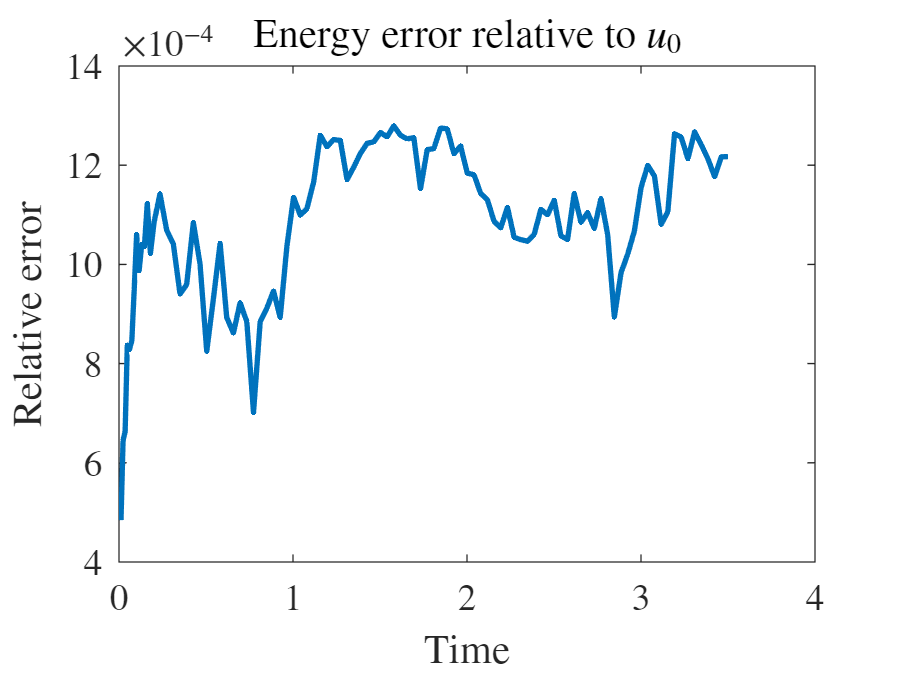

energyDiff = zeros(floor(n/scale),1);
massDiff = zeros(floor(n/scale),1);
tplot = zeros(floor(n/scale),1);
% C = Phi.weightMatrixWithBCs;
% Cinv = pinv(C);
D = Phi.derivative;

u0energy = Phi.dot( D*u(:,1) , conj(D*u(:,1)) ) - Phi.dot( u(:,1).^2 , conj(u(:,1)).^2 );
u0mass = Phi.dot(u(:,1),conj(u(:,1)));
u0momentum = Phi.dot(conj(u(:,1)).^2,(D*u(:,1)).^2);

for i=1:floor(n/scale)
    ui = u(:,scale*i);
    uiprime=D*ui;
%     energyDiff(i) = abs( (0.5*(Phi.dot(Cinv*A*ui,conj(ui)) - Phi.dot(ui.^2,conj(ui.^2))) - u0energy) / u0energy );
    term1 = Phi.dot(uiprime,conj(uiprime));
    term2 = Phi.dot(ui.^2,conj(ui).^2);
    E = term1 - term2;
    
    energyDiff(i) = abs((E-u0energy)/u0energy);
    massDiff(i) = abs( (Phi.dot(ui,conj(ui)) - u0mass) / u0mass );
    momentumDiff(i) = abs( (Phi.dot(conj(ui).^2,uiprime.^2) - u0momentum) / u0momentum );
    tplot(i) = t(scale*i);
end

disp('')
figure
plot(tplot,energyDiff)
title('Energy error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')

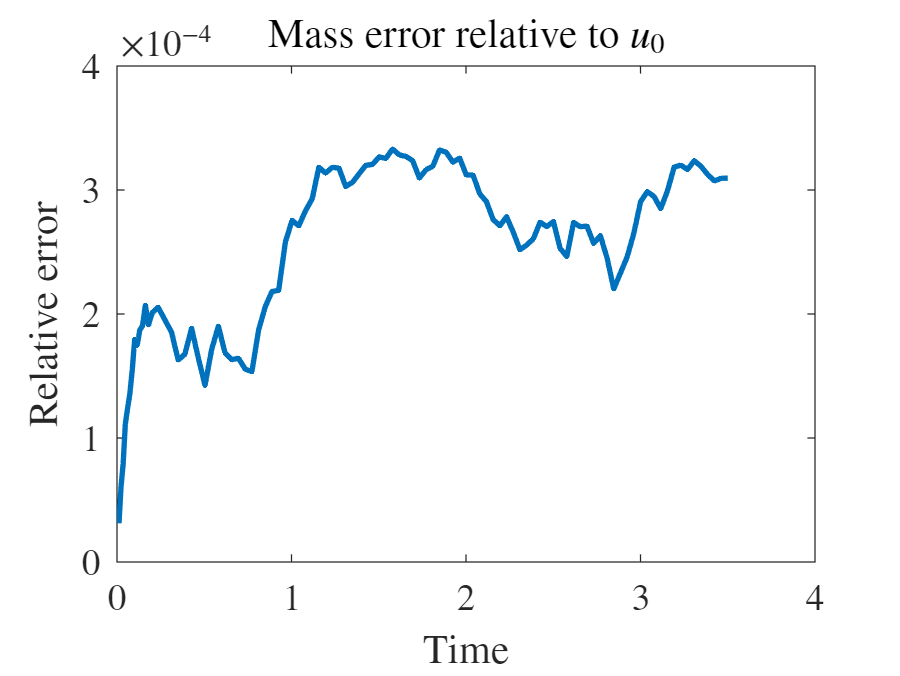


figure
plot(tplot,massDiff)
title('Mass error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')

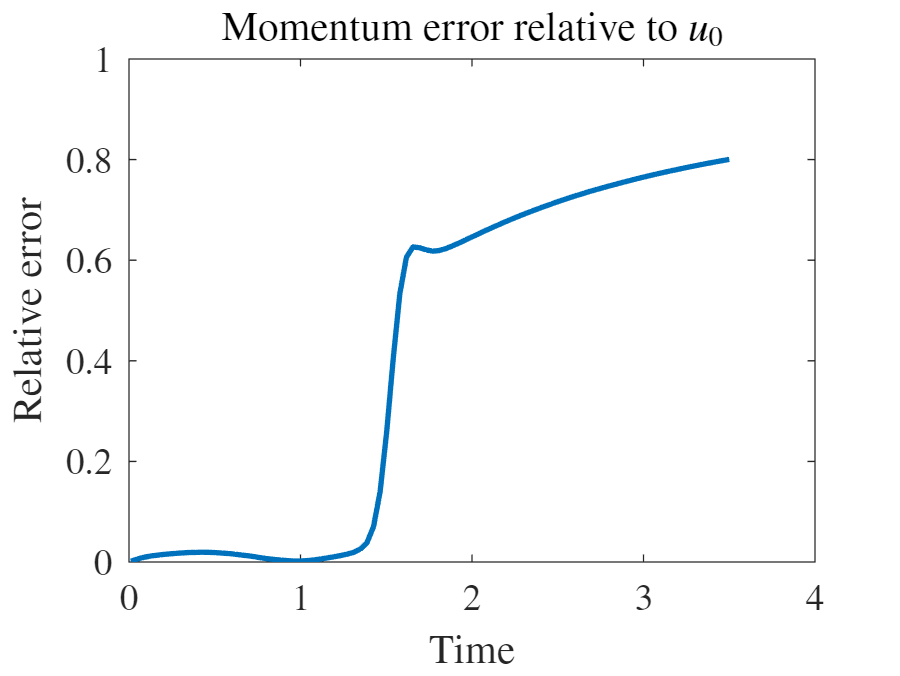


figure
plot(tplot,momentumDiff)
title('Momentum error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')